# Debi's Cube - Solution

Wirtten by: Doron Serebro

## Load The Data

The first step is to read the hyperspectral cube and extract it's dimension

data=enviread_new('bimodal.dat');

bands_2_read = 0

bands_2_read =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


NOTE : The matrix form is lines(rows)*samples(columns)*bands(spectrum)


dmax=max(data(:));
data_for_viewing=data/dmax*255;  % this line is used for visualisation later
[y_size, x_size, num_of_bands]=size(data); % pic size

## Visualise the Data

Let's understand what type of data are we dealing with here:

size(data)

ans =     50    50    91


So our cube is 50x50x91 which means that we have a total of 91 channels/2D-images of size 50x50. Let's look at some of them:

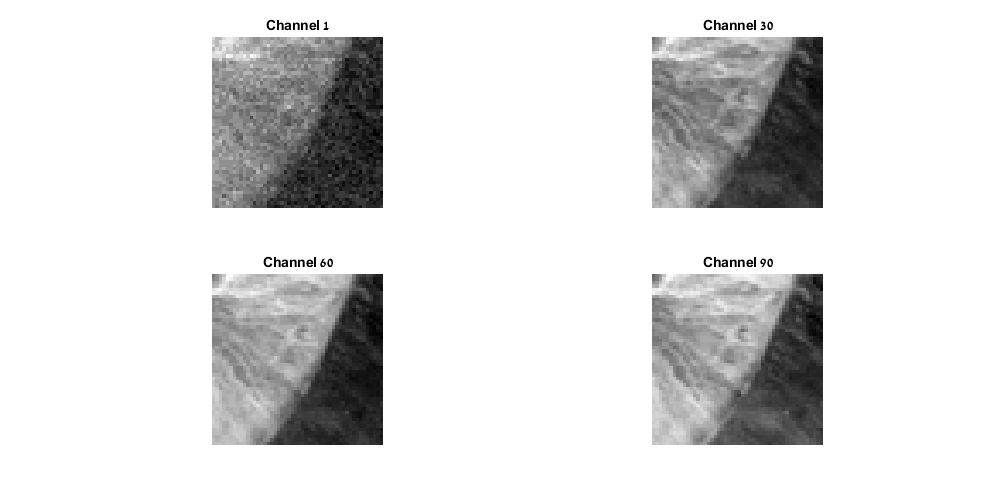

h1=figure;
subplot(2,2,1)
imshow(data_for_viewing(:,:,1),[]);
title("Channel 1")
subplot(2,2,2)
imshow(data_for_viewing(:,:,30),[]);
title("Channel 30")
subplot(2,2,3)
imshow(data_for_viewing(:,:,60),[]);
title("Channel 60")
subplot(2,2,4)
imshow(data_for_viewing(:,:,90),[]);
title("Channel 90")
set(h1, 'Position', [0 0 1000 500])

## Define Constants

Let us recall that the Matched Fileter (MF) algorithm is given by: $\mathrm{MF}\left(x\right)=t^T \phi {\;}^{-1} \left(x-m\right)$. We first need to define:

- the target signature - this is what we're looking for. a target signature is obtained by slicing the cube along the 3rd dimension to get a 91x1 vector.

- the percentage of the target we plan to implant in each pixel - the default is 1%.

- the threshold of tolerable false alarm - we will start with 0.1 and modify this later on.

t=squeeze(data(5,3,:)); 
p=0.01; 
th=0.1;

## Calculate Statistic Properties

Now we will calculate $m$ and $\phi \;$:

$m$ is actually an estimator of the cube $x$. The estimation is fairly simple, and is done per-channel (1 image at a time). The estimator for every pixel is simply the mean of his immidiate neighbors.  Instead of calculating this directly (using loops and adressing edge cases), we can compute this quite easily using convolution. Suppose $X$ is a 3x3 matrix of a given 2D-pixel and its neighbors, we can calculate $m\;$ like so:


$$m\left(i,j,\lambda \right)=\frac{1}{8}\sum_{\mathrm{all}\;\mathrm{neighbors}} \;X=\frac{1}{8}\left(X*\left\lbrack \begin{array}{ccc}
1 & 1 & 1\\
1 & 1 & 1\\
1 & 1 & 1
\end{array}\right\rbrack -X\left(2,2\right)\right)\;$$


Convolving X with a matrix of ones gives us the sum of all elements in X. by subtracting the center pixel we get what we need. This is nice, since now we don't have to take into account edge pixels which have 5 neighbors and corner pixels with only 3 neighbors. The only considiration for edges is dividing by the correct number of neighbors. For this, we have the function build_norm_mat that builds a normalizing matrix of the desired size (see documentation for details).

M = zeros(size(data));
data_sum = zeros(size(data));
sum_filter = ones(3); %filter for using convolution as sum of neighbors

%build a matrix to normalize each summed element back to original scale
normalize=build_norm_mat(x_size,y_size);

for z=1:num_of_bands
    curr_band=squeeze(data(:,:,z));
    data_sum(:,:,z) = conv2(curr_band,sum_filter,'same') ; % sum up the 3x3 neighborhood
    M(:,:,z)=(data_sum(:,:,z)-curr_band)./normalize; % remove center and normalize
end

Let's visualise our estimator:

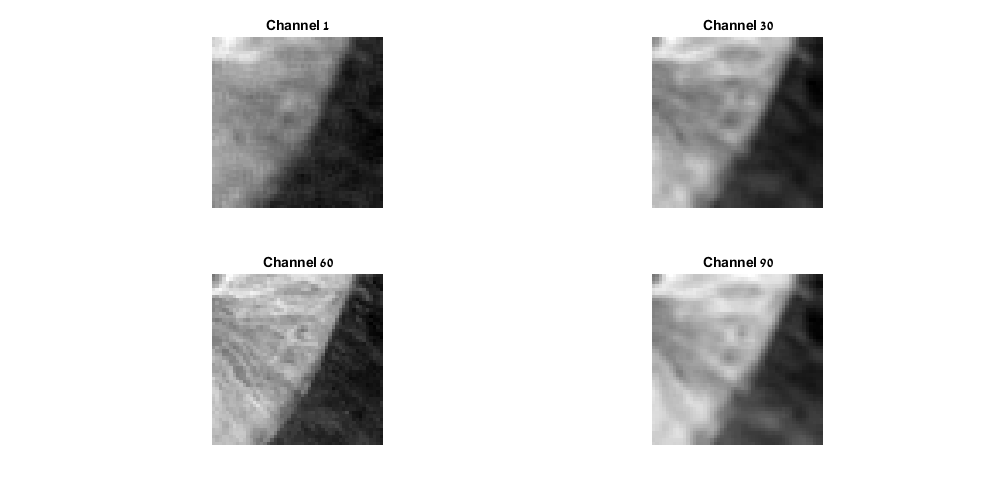

h3=figure;
subplot(2,2,1)
imshow(M(:,:,1),[]);
title("Channel 1")
subplot(2,2,2)
imshow(M(:,:,30),[]);
title("Channel 30")
subplot(2,2,3)
imshow(data_for_viewing(:,:,60),[]);
title("Channel 60")
subplot(2,2,4)
imshow(M(:,:,90),[]);
title("Channel 90")
set(h3, 'Position', [0 0 1000 500])

## Calculating $\phi \;$

The covariance matrix we are looking for is actually the auto-covariance matrix of the cube. but wait, isn't auto-covariance matrix is obtained from a random vector? how can we do this for a 3D-matrix? The truth is that our cube is in fact a random vector!

In order to understand that, we must return to the basics. In MATLAB,  a random variable is represented by a vector of samples from the distribution of that variable. This allows us to talk about statistical properties like mean and variance. This means that a random vector would actually be a matrix where each row represents a single random variable.

In our case, the random variables are the 91 images. Each image is a random variable who's been sampled many tiems and organized in a matrx. It will still have exatly the same statistical poperties if concatenate its rows to form an actual vector (turning every 50x50 image to a 2500x1 vector). Now every image retains it's mean and variance but we can now represent our cube is a random vector of length 91.

$\phi =E\left\lbrack {\left(X-M\right)\left(X-m\right)}^T \right\rbrack$ is the autocovariance matrix of our newly formed random vector of size 91x2500. 

X_MINUS_M=data-M;
phi = cov( reshape(X_MINUS_M,x_size*y_size,num_of_bands) );
size(phi)

ans =     91    91


## Matched Filter

Now we can finally run the MF algorithm like we wanted to: $\mathrm{MF}\left(x\right)=t^T \phi {\;}^{-1} \left(x-m\right)$

Let's just recall that we want to run the algorithm twice per 3D-pixel:

- run the algorithm with no target (NT)

- plant a percentage of the target in every pixel (WT)

We start by allocating rooms for our results:

MF_NT = zeros(x_size,y_size);
MF_WT = zeros(x_size,y_size);

A nice trick is to calculate $t^t \phi {\;}^{-1}$ ahead of time. This saves us a lot of runtime since matrix inversion is computationally expensive

t_phi_inv=t'*pinv(phi);

Now we can loop over each pixel and calculate it's NT score and WT score:

for i=1:x_size
    for j=1:y_size
        x_minus_m=squeeze(X_MINUS_M(i,j,:)); %define a vector of pixels x
        x_wt=x_minus_m+p*t;
        MF_NT(i,j)=t_phi_inv*x_minus_m;
        MF_WT(i,j)=t_phi_inv*x_wt;
    end
end

## Visualising Results and Evaluating Performance

Each result matrix would store the MF score of each pixel. In a real life situation high score for a certain pixel would indicate likelyhood of a target being in that pixel. In our case, we're trying artificailly to evaluate the performance of the MF algorithm so we're not interested in the actual scores. Our goal is to to generate a ROC curve. This is done in a few steps:

- generate a histogram of the results

- Normalise it to compute an Inverse Cumulative Probability Distribution

- Flip and align the 2 vectors

- plot $P_d$ as a function of $P_{\mathrm{fa}}$

## Histogram

Let's generate a histogram first:

(for details see MATLAB's documentation of [histcounts](https://www.mathworks.com/help/matlab/ref/histcounts.html))

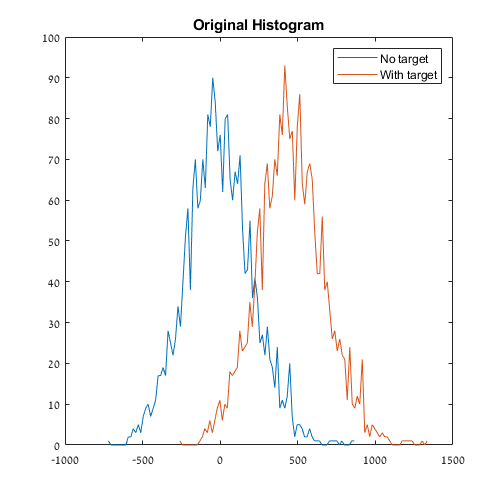

[NT_val,NT_bins]=histcounts(MF_NT,100);
[WT_val,WT_bins]=histcounts(MF_WT,100);

h4=figure();
plot(NT_bins(1:100),NT_val);
hold on;
plot(WT_bins(1:100),WT_val);
title('Original Histogram');
legend('No target','With target');
hold off;
set(h4, 'Position', [0 0 500 500])

##  Inverse Cumulative Probability Distribution

Now let's create the Inverse Cumulative Probability Distribution. This is done by dividing our histogram by number of elements. This creates a probability distribution since we have a non-negative vector that starts at 0 and the sum of all elements is 1. The last step is to invert the distribution:

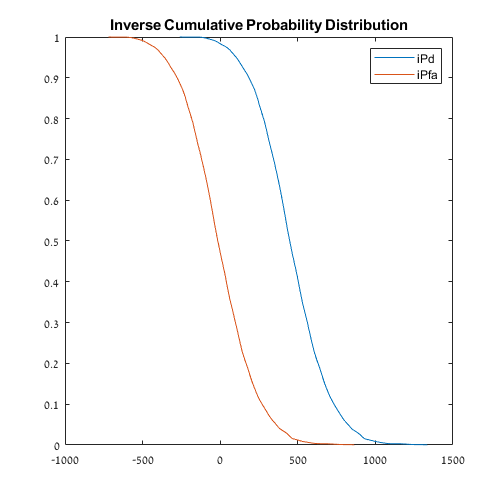

ipd  = 1-cumtrapz(WT_val)/(x_size*y_size);       %calculate WT distribution
ipfa = 1-cumtrapz(NT_val)/(x_size*y_size);       %calculate NT distribution


h5=figure();
plot(WT_bins(1:100),ipd)
hold on;
plot(NT_bins(1:100),ipfa)
title('Inverse Cumulative Probability Distribution');
legend('iPd','iPfa');
hold off;
set(h5, 'Position', [0 0 500 500])

## ROC Curve

The ROC curve is a plot of $P_d$ as a function of $P_{\mathrm{fa}}$. In order to do this, we must first notice that while the $P_d$ and $P_{\mathrm{fa}}$ are vectors of the same length, they do not overlap (if we look at the histogram we can see that $P_{\textrm{fa}}$ has is roguhly in range [-750, 750] while $P_d$ has is roguhly in range [-250, 1250]). We need to zero pad both vectors in order to correctly plot our ROC curve:

end_of_nt_in_wt = 100-find(WT_bins>NT_bins(end),1,'first');
start_of_wt_in_nt = find(NT_bins>WT_bins(1),1,'first');  
size_to_add = max(end_of_nt_in_wt,start_of_wt_in_nt);

pd = [zeros(1,size_to_add) ipd];
pfa = [ipfa zeros(1,size_to_add)];

One last step is to flip the order of elements in each vector. This will return our inverse distribution to a simple distribution:

pfa = fliplr(pfa);
pd = fliplr(pd);


Now we can plot our ROC curve:

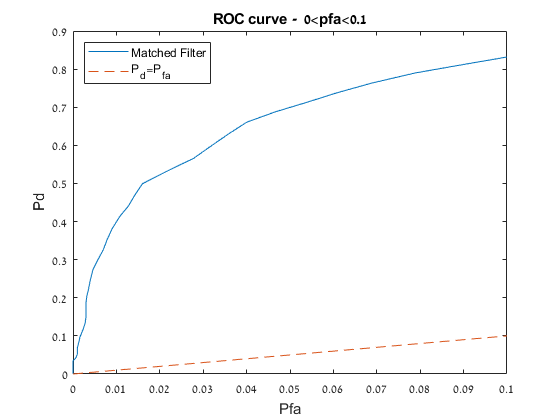

figure()
plot(pfa,pd)
hold on
plot([0 th],[0 th],'--')
title('ROC curve -  0<pfa<0.1');
xlabel('Pfa');
ylabel('Pd');
legend('Matched Filter','P_d=P_{fa}','Location','northwest')
xlim([0 th])

## Evaluating Performance

Let's recall the definition of $A_{\mathrm{th}}$:


$$A_{\mathrm{th}} =\frac{A-0\ldotp 5{\left(\mathrm{th}\right)}^2 }{\mathrm{th}-0\ldotp 5{\left(\mathrm{th}\right)}^2 }$$


This metric represents the normalised area under the ROC graph from 0 until our threshold $\mathrm{th}$. Let's see the values of $A_{\mathrm{th}}$ for a few different values of $\mathrm{th}$:

%% calculate Ath
pd_masked=pd;
Ath=zeros(1,3);
idx=1;
for th=[0.1, 0.01, 0.001]
    pd_masked(pfa>th)=0;
    A_vect=cumtrapz(pfa,pd_masked);
    A=A_vect(end);
    Ath(idx)=(A-0.5*th^2)/(th-0.5*th^2);
    fprintf("for th=%.3f, Ath=%.3f\n",th,Ath(idx))
    idx=idx+1;
end

for th=0.100, Ath=0.661
for th=0.010, Ath=0.237
for th=0.001, Ath=0.036
